Boundary Value Problems!

Finite Difference Method

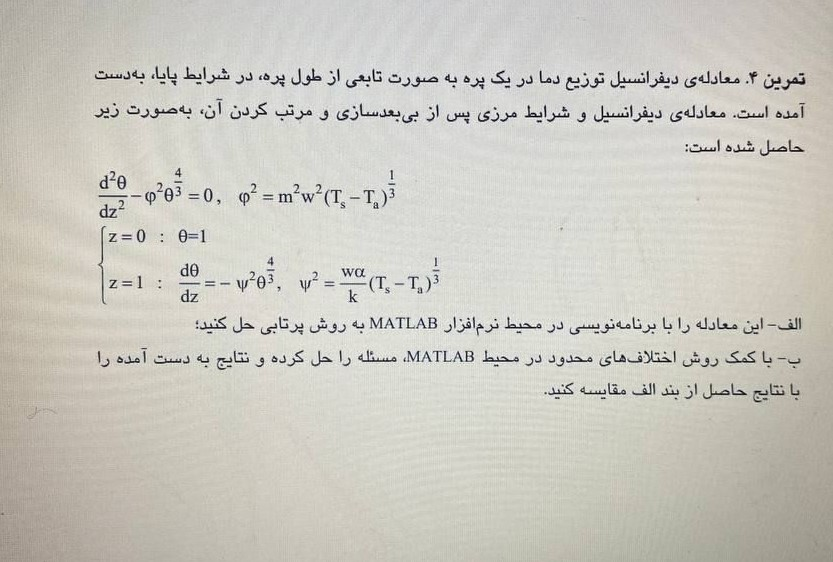

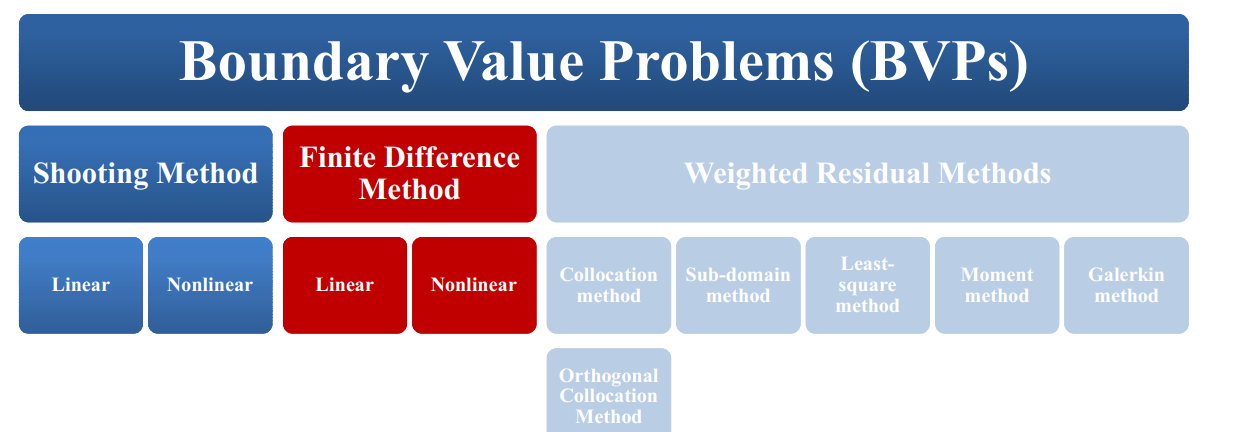

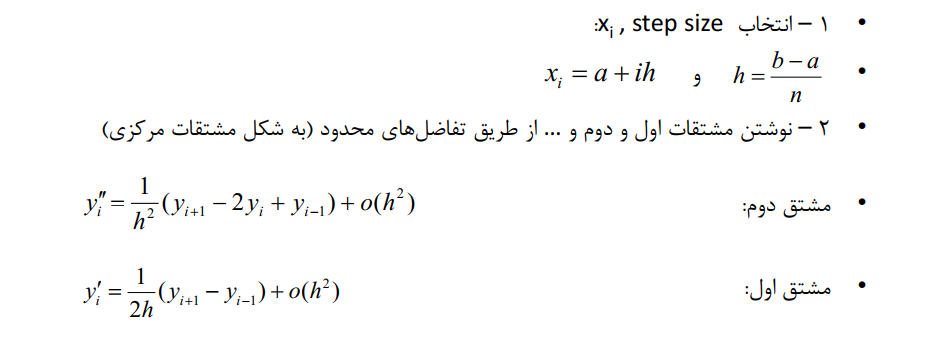

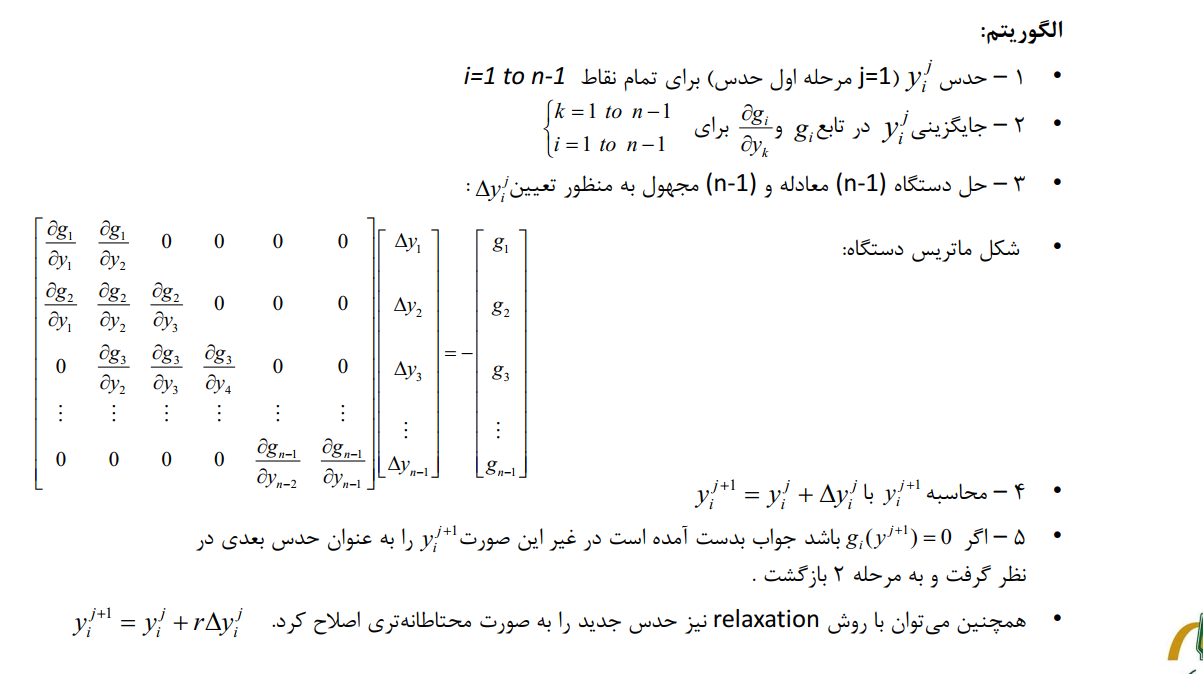


$$\begin{array}{l}
\mathrm{ODE}:\\
\frac{1}{h^2 }\left(y_{i+1} -2*y_i +y_{i-1} \right)=\mathrm{M1}*y_i^{\frac{4}{3}} ;\\
\mathrm{at}\;\mathrm{the}\;\mathrm{first}\;\mathrm{Point}:y_0 =1;\\
\mathrm{at}\;\mathrm{the}\;\mathrm{final}\;\mathrm{point}:y_{i+1} -y_i =h*\left(-\mathrm{M2}*y_i^{\frac{4}{3}} \right)
\end{array}$$


clear; clc; close all;

% initilizations:
m = 1;   w = 2; Ts  =210; Ta = 180; alpha = 0.2; k = 1; 

h = 0.05; % Step Size
b=1; a=0.01;
interval=b-a;
num_of_lines = round(interval/h);


global MULTING  MULTING2

MULTING = m^2 * w^2 * (Ts - Ta)^(1/3);
MULTING2 = w*alpha/k*(Ts - Ta)^(1/3) ;

Y  = zeros(num_of_lines,1);
A = zeros(num_of_lines,num_of_lines); % Coefficient Matrix
g = Y;

y0 = 1;

iter_max = 10;

threshold = 1e-3;




for iter =1 :iter_max
    % Obtain Coefficient Matrix:
    for i=1:length(Y)
        for j=1:length(Y)
            if(i==j)
            A(i,j) = h^2 * MULTING*4/3*Y(i)+2;
            elseif(abs(j-i)==1)
            A(i,j) =-1;
            end
    
        end
        if((i>2) && (i<length(Y)))
            g(i,1)  = h^2*MULTING*Y(i,1).^4/3 - Y(i+1,1) + 2*Y(i,1) - Y(i-1,1) ;
        elseif(i==1)
            g(i,1)  = h^2*MULTING*Y(i,1).^4/3 - Y(i+1,1) + 2*Y(i,1) - y0 ;
        elseif(i==length(Y))
            g(i,1)  = h^2*MULTING*Y(i,1).^4/3 - (-2*h*MULTING2*Y(i,1).^4/3 + Y(i,1)) + 2*Y(i,1) - Y(i-1,1) ;
        end
    end
    
    delta_Y =  - g'*pinv(A);
    Y = Y + delta_Y';
    % CHeck Convergence:
    if(norm(g)<threshold)
        return
    end

end



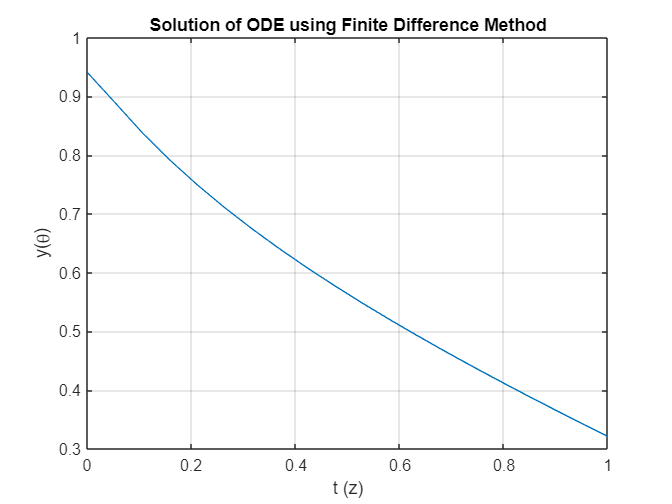


t = linspace(0,1,length(Y(:,1)));
figure(1)
plot(t,Y(:,1));
grid on
ylabel("y(\theta)")
xlabel("t (z)")
title("Solution of ODE using Finite Difference Method")